# **P4.20**

We are to repeat the task from problem 4.17 but this time using an RBF network with modifiable parameters $k$, the number of centers and $\sigma \;$the standard deviation of the gaussians.

The output of an RBF network is obtained using:


$$g\left(x\right)=w_0 +\sum_i \;w_i \;\exp \left\lbrace -\frac{{\left(x-c_i \right)}^T \left(x-c_i \right)}{2\sigma_i^2 }\right\rbrace$$


We will assume all the basis functions have the same standard deviation and we will only provide the number of centers.

We will train the weights of the perceptron part of the RBF network using the least squares method (the pseudo-inverse rule), i.e.:


$$W^* ={\left(x^T x\right)}^{-1} x^T y\;\left(\mathrm{or}\;\mathrm{pinv}\left(x\right)\times \;y\right)$$


We will test the following configurations on of the RBF network:

- 
$$k=3,\sigma =0\ldotp 5$$


- 
$$k=20,\sigma =0\ldotp 1$$


- 
$$k=1,\sigma =1$$


First up, we will generate the train and test sets the same way as before in 4.17.

x_train = linspace(0, 1, 20);
y_train = 0.3 + 0.2*cos(2*pi*x_train);
% x_test is 50 samples chosen uniformly from (0, 1)
x_test = rand([1, 50]);
y_test = 0.3 + 0.2*cos(2*pi*x_test);

## Testing for Config 1 (k = 3, sigma = 0.5)

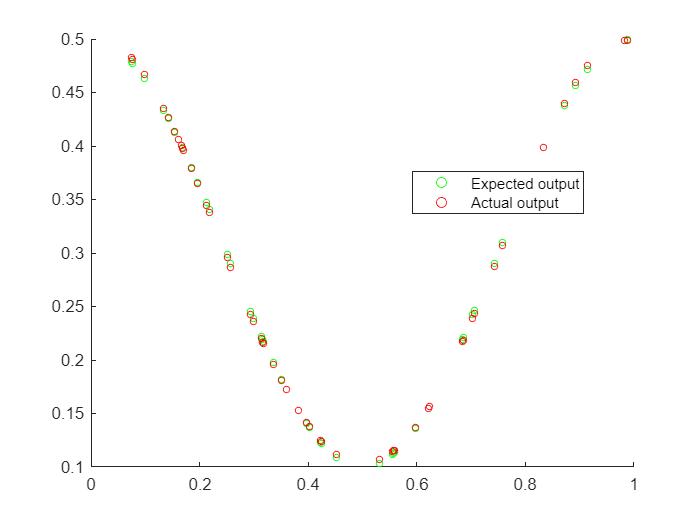

k = 3;
sigma = 0.5;
X_RBF = [];
% create k linearly spaced centers
centers = linspace(0, 1, k);
% for every sample in the training set calculate all of the basis functions
% for every available gaussian and append it to the current running list of
% RBF outputs which are the inputs of the single layer perceptron following
% the RBF nodes.
for i=1:length(x_train)
    basis_functions = [];
    for j=1:k
        basis_functions = [basis_functions ...
            exp(-norm(x_train(i)-centers(j))^2)/(2*sigma^2)];
    end
    % augment the output with a "1" for the bias term.
    X_RBF = [X_RBF; 1 basis_functions];
end
% calculate optimal weights using the LS method
W = pinv(X_RBF)*y_train';
% now we will obtain the RBF outputs for the test set
X_RBF = [];
for i=1:length(x_test)
    basis_functions = [];
    for j=1:k
        basis_functions = [basis_functions ...
            exp(-norm(x_test(i)-centers(j))^2)/(2*sigma^2)];
    end
    % augment the output with a "1" for the bias term.
    X_RBF = [X_RBF; 1 basis_functions];
end
% calculate the output of the network with the weights obtained from the
% previous step
net_out = X_RBF*W;
% plot the results
scatter(x_test,y_test,15,'green')
hold on
scatter(x_test,net_out,15,'red')
legend('Expected output', 'Actual output', 'location', 'best')
hold off

fprintf('MSE: %d', mean((net_out-y_test).^2,'all'));

MSE: 3.348078e-02

As we can see, even with such a small number of neurons the RBF achieves a high accuracy on the test set. This was to be expected because we intentionally set the number of centers to 3 as the sinosoidal function in the given interval $\left\lbrack 0,1\right\rbrack$ has three peaks, each of which can be described by one basis function. We also set the standard deviation value low enough that the basis functions do not affect each other too much.

## Testing for Config 2 (k=20, sigma=0.1)

We will repeat the same exact experiment for config 2.

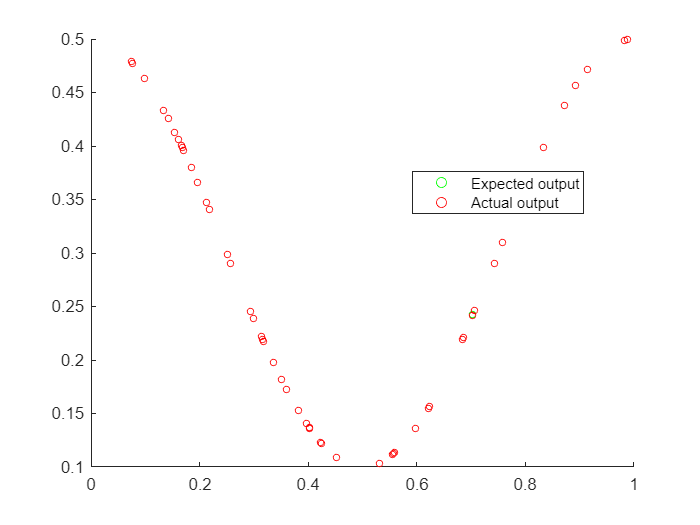

k = 20;
sigma = 0.1;
X_RBF = [];
centers = linspace(0, 1, k);
for i=1:length(x_train)
    basis_functions = [];
    for j=1:k
        basis_functions = [basis_functions ...
            exp(-norm(x_train(i)-centers(j))^2)/(2*sigma^2)];
    end
    X_RBF = [X_RBF; 1 basis_functions];
end
W = pinv(X_RBF)*y_train';
X_RBF = [];
for i=1:length(x_test)
    basis_functions = [];
    for j=1:k
        basis_functions = [basis_functions ...
            exp(-norm(x_test(i)-centers(j))^2)/(2*sigma^2)];
    end
    X_RBF = [X_RBF; 1 basis_functions];
end
net_out = X_RBF*W;
scatter(x_test,y_test,15,'green')
hold on
scatter(x_test,net_out,15,'red')
legend('Expected output', 'Actual output', 'location', 'best')
hold off

fprintf('MSE: %d', mean((net_out-y_test).^2,'all'));

MSE: 3.339855e-02

As we can see if we have as many centers as we have inputs, the accuracy is even higher than before and MSE is less than the previous config.

## Testing for Config 3 (k=1, sigma=1)

We do not expect this network to have the capacity to describe the dataset but we will attempt to train it nevertheless and observe the results.

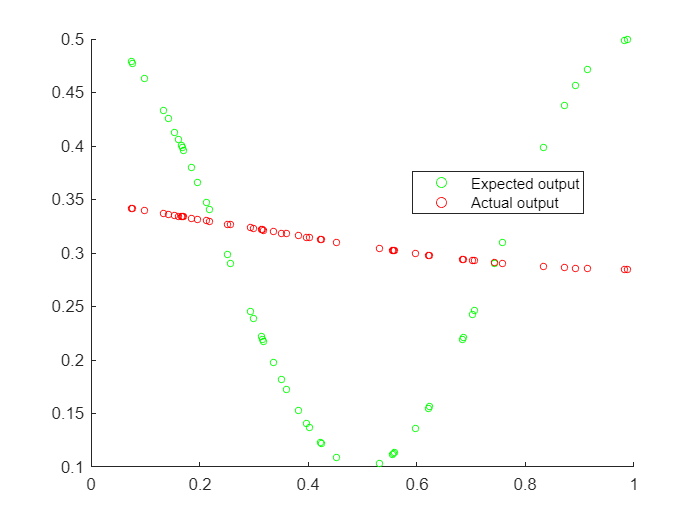

k = 1;
sigma = 1;
X_RBF = [];
centers = linspace(0, 1, k);
for i=1:length(x_train)
    basis_functions = [];
    for j=1:k
        basis_functions = [basis_functions ...
            exp(-norm(x_train(i)-centers(j))^2)/(2*sigma^2)];
    end
    X_RBF = [X_RBF; 1 basis_functions];
end
W = pinv(X_RBF)*y_train';
X_RBF = [];
for i=1:length(x_test)
    basis_functions = [];
    for j=1:k
        basis_functions = [basis_functions ...
            exp(-norm(x_test(i)-centers(j))^2)/(2*sigma^2)];
    end
    X_RBF = [X_RBF; 1 basis_functions];
end
net_out = X_RBF*W;
scatter(x_test,y_test,15,'green')
hold on
scatter(x_test,net_out,15,'red')
legend('Expected output', 'Actual output', 'location', 'best')
hold off

fprintf('MSE: %d', mean((net_out-y_test).^2,'all'));

MSE: 1.800364e-02

As we can see the output is not satisfactory and the MSE is much higher than the previous two configs. This is because one basis function simply cannot describe the three peaks of the sinusoidal in $\left\lbrack 0,1\right\rbrack$.